%% Transmitter
clear all;
seed = 1; % seed 1 is a magic number 
rng(seed);

output_track = [];

frames = randi([0,1],100,100); % 100 frames, each 100 bits

% Set first 8 bits to ID
for i = 1:100
    tempstr = dec2bin(i,8);
    for j = 1:8
        frames(i,j) = int32(str2double(tempstr(j)));
    end
end

t = 0:1/44100:1; % A temporary time vector for 1 second
fc = 10*10^3; % Carrier frequency 10kHz
carrier = sin(2*pi*fc*t); % Approximately 1 second
% Initialize CRC Generator
crc8 = comm.CRCGenerator('Polynomial', [1,1,0,1,0,0,1,1,1]);

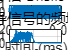

% Preamble: 440 samples
f_p = [linspace(10*10^3-8*10^3,10*10^3,220), linspace(10*10^3,10*10^3-8*10^3,220)]; 
omega = 2*pi .* cumtrapz(t(1:440), f_p);
preamble = sin(omega);
% 绘制时域图
figure;
subplot(2,1,1);
plot(0:1/44100:439/44100, preamble);
xlabel('时间 (ms)');
ylabel('振幅');
title('前导信号的时域图');
grid on;

% 计算并绘制频域图
% 使用 FFT 进行频谱分析
NFFT = 2^nextpow2(440);  % FFT 点数
P = fft(preamble, NFFT) / 440;
f = 44100/2 * linspace(0,1,NFFT/2+1);

% 绘制单边幅度谱
subplot(2,1,2);
plot(f/1e3, 2*abs(P(1:NFFT/2+1)));
xlabel('频率 (kHz)');
ylabel('|P(f)|');
title('前导信号的频域图');
grid on;

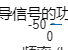


% 可选：绘制功率谱密度（使用 MATLAB 的 pwelch 函数）
figure;
pwelch(preamble, [], [], [], 44100);
title('前导信号的功率谱密度');


for i = 1:100
    frame = frames(i,:);
    
    % Add CRC
    frame_col = frame.'; % Convert to column vector
    frame_crc_col = step(crc8, frame_col); % Generate CRC (column vector)
    frame_crc = [frame, frame_crc_col.']; % Concatenate original frame and CRC (row vector)
    
    % Modulation
    frame_wave = zeros(1, length(frame_crc) * 44);
    for j = 0:length(frame_crc)-1
        start_idx = 1 + j*44;
        end_idx = 44 + j*44;
        frame_wave(start_idx:end_idx) = carrier(start_idx:end_idx) * (frame_crc(j+1)*2 - 1); % Baud rate 44/44100 ~ 1000bps
    end

    % Add preamble
    frame_wave_pre = [preamble, frame_wave];
    
    % Append to output_track with random inter-frame space
    % output_track = [output_track, zeros(1, int32(rand()*100))]; % Add random inter-frame space
    output_track = [output_track, frame_wave_pre];
    % output_track = [output_track, zeros(1, int32(rand()*100))];
end 

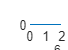


% Play the sound (uncomment if desired)
% sound(output_track, 44100);

% Cross-correlation with preamble (uncomment if desired)
temp = xcorr(output_track, preamble);
plot(temp);


temp_out = output_track(1:4410)

temp_out =          0    0.2836    0.5483    0.7696    0.9252    0.9967    0.9731    0.8518    0.6407    0.3581    0.0318   -0.3029   -0.6072   -0.8429   -0.9774   -0.9892   -0.8713   -0.6342   -0.3059    0.0703    0.4411    0.7502    0.9475    0.9971    0.8852    0.6245    0.2541   -0.1652   -0.5597   -0.8559   -0.9945   -0.9432   -0.7055   -0.3232    0.1299    0.5603    0.8745    0.9995    0.9010    0.5946    0.1457   -0.3424   -0.7516   -0.9771   -0.9562   -0.6868   -0.2331    0.2875    0.7337    0.9781


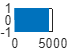

plot(temp_out)

% Plot the output track (uncomment if desired)
% figure;
% plot(output_track);